% Date created: 221219

% This script takes SPT data from HaloTag-PBP2B and makes violin DABEST
% plots of the number of runs per track under various conditions.

## User parameters

speedcut = [5 50]; % [nm/s]
interval = 1; % [s] acquisition interval

## Load data

datadir = '\\campus\rdw\FMS CBCB\nsh167\Shared\data\Whitley-Kevin\Data_Analyzed\PBP2B_results\';

cdm30_file = '221128_sh147_cdm_30c_vercini_kymo_unreg_clean_polyline.mat';
cdm37_file = '221207_sh147_cdm_37c_vercini_kymo_unreg_clean_polyline.mat';
phmm30_file = '221111_sh147_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';
phmm37_file = '221122_sh147_phmm_37c_vercini_kymo_unreg_clean_polyline.mat';

pc19_file = '221115_sh147_phmm_30c_pc19_vercini_kymo_unreg_clean_polyline.mat';
penG_file = '221116_sh147_phmm_30c_penG_vercini_kymo_unreg_clean_polyline.mat';
fos_file = '221116_sh147_phmm_30c_fosfomycin_vercini_kymo_unreg_clean_polyline.mat';
g106s_file = '221208_sh147sh056_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';

open([datadir cdm30_file])

ans = struct with fields:
    cdm30_life: [1016×16 table]


open([datadir cdm37_file])

ans = struct with fields:
    cdm37_life: [1542×16 table]


open([datadir phmm30_file])

ans = struct with fields:
    phmm30_life: [1572×16 table]


open([datadir phmm37_file])

ans = struct with fields:
    phmm37_life: [1996×16 table]



open([datadir pc19_file])

ans = struct with fields:
    phmm30_pc19_life: [1337×16 table]


open([datadir penG_file])

ans = struct with fields:
    phmm30_penG_life: [1537×16 table]


open([datadir fos_file])

ans = struct with fields:
    phmm30_fos_life: [1167×16 table]


open([datadir g106s_file])

ans = struct with fields:
    phmm30_g106s_life: [362×16 table]


## Get numbers of runs per track and fraction of runs per track

% MAKE NEW TABLES WITH COLUMN FOR NUMBER OF SEGMENTS AND NUMBER OF RUNS PER
% TRACK

cdm30_full = fullTrack_n_runs(cdm30_life, speedcut);
cdm37_full = fullTrack_n_runs(cdm37_life, speedcut);
phmm30_full = fullTrack_n_runs(phmm30_life, speedcut);
phmm37_full = fullTrack_n_runs(phmm37_life, speedcut);

pc19_full = fullTrack_n_runs(phmm30_pc19_life, speedcut);
penG_full = fullTrack_n_runs(phmm30_penG_life, speedcut);
fos_full = fullTrack_n_runs(phmm30_fos_life, speedcut);
g106s_full = fullTrack_n_runs(phmm30_g106s_life, speedcut);

% MAKE LISTS OF NUMBERS OF RUNS PER TRACK

cdm30_n_runs = cdm30_full.n_runs(~isnan(cdm30_full.n_runs));
cdm37_n_runs = cdm37_full.n_runs(~isnan(cdm37_full.n_runs));
phmm30_n_runs = phmm30_full.n_runs(~isnan(phmm30_full.n_runs));
phmm37_n_runs = phmm37_full.n_runs(~isnan(phmm37_full.n_runs));

pc19_n_runs = pc19_full.n_runs(~isnan(pc19_full.n_runs));
penG_n_runs = penG_full.n_runs(~isnan(penG_full.n_runs));
fos_n_runs = fos_full.n_runs(~isnan(fos_full.n_runs));
g106s_n_runs = g106s_full.n_runs(~isnan(g106s_full.n_runs));

% means and errors for n_runs

cdm30_n_runs_mean = mean(cdm30_n_runs);
cdm37_n_runs_mean = mean(cdm37_n_runs);
phmm30_n_runs_mean = mean(phmm30_n_runs);
phmm37_n_runs_mean = mean(phmm37_n_runs);

pc19_n_runs_mean = mean(pc19_n_runs);
penG_n_runs_mean = mean(penG_n_runs);
fos_n_runs_mean = mean(fos_n_runs);
g106s_n_runs_mean = mean(g106s_n_runs);

cdm30_n_runs_sem = std(cdm30_n_runs) / sqrt(length(cdm30_n_runs));
cdm37_n_runs_sem = std(cdm37_n_runs) / sqrt(length(cdm37_n_runs));
phmm30_n_runs_sem = std(phmm30_n_runs) / sqrt(length(phmm30_n_runs));
phmm37_n_runs_sem = std(phmm37_n_runs) / sqrt(length(phmm37_n_runs));

pc19_n_runs_sem = std(pc19_n_runs) / sqrt(length(pc19_n_runs));
penG_n_runs_sem = std(penG_n_runs) / sqrt(length(penG_n_runs));
fos_n_runs_sem = std(fos_n_runs) / sqrt(length(fos_n_runs));
g106s_n_runs_sem = std(g106s_n_runs) / sqrt(length(g106s_n_runs));

% MAKE LISTS OF FRACTIONS OF RUN SEGMENTS PER TRACK

cdm30_f_runs = cdm30_n_runs ./ cdm30_full.n_segs(~isnan(cdm30_full.n_segs));
cdm37_f_runs = cdm37_n_runs ./ cdm37_full.n_segs(~isnan(cdm37_full.n_segs));
phmm30_f_runs = phmm30_n_runs ./ phmm30_full.n_segs(~isnan(phmm30_full.n_segs));
phmm37_f_runs = phmm37_n_runs ./ phmm37_full.n_segs(~isnan(phmm37_full.n_segs));

pc19_f_runs = pc19_n_runs ./ pc19_full.n_segs(~isnan(pc19_full.n_segs));
penG_f_runs = penG_n_runs ./ penG_full.n_segs(~isnan(penG_full.n_segs));
fos_f_runs = fos_n_runs ./ fos_full.n_segs(~isnan(fos_full.n_segs));
g106s_f_runs = g106s_n_runs ./ g106s_full.n_segs(~isnan(g106s_full.n_segs));

% means and errors for f_runs

cdm30_f_runs_mean = mean(cdm30_f_runs);
cdm37_f_runs_mean = mean(cdm37_f_runs);
phmm30_f_runs_mean = mean(phmm30_f_runs);
phmm37_f_runs_mean = mean(phmm37_f_runs);

pc19_f_runs_mean = mean(pc19_f_runs);
penG_f_runs_mean = mean(penG_f_runs);
fos_f_runs_mean = mean(fos_f_runs);
g106s_f_runs_mean = mean(g106s_f_runs);

cdm30_f_runs_sem = std(cdm30_f_runs) / sqrt(length(cdm30_f_runs));
cdm37_f_runs_sem = std(cdm37_f_runs) / sqrt(length(cdm37_f_runs));
phmm30_f_runs_sem = std(phmm30_f_runs) / sqrt(length(phmm30_f_runs));
phmm37_f_runs_sem = std(phmm37_f_runs) / sqrt(length(phmm37_f_runs));

pc19_f_runs_sem = std(pc19_f_runs) / sqrt(length(pc19_f_runs));
penG_f_runs_sem = std(penG_f_runs) / sqrt(length(penG_f_runs));
fos_f_runs_sem = std(fos_f_runs) / sqrt(length(fos_f_runs));
g106s_f_runs_sem = std(g106s_f_runs) / sqrt(length(g106s_f_runs));

## Prepare for plotting

% BIN DATA FOR NUMBER OF RUNS PER TRACK

bin_cdm30 = histcounts(cdm30_n_runs, 0:8, 'Normalization', 'probability');
bin_cdm37 = histcounts(cdm37_n_runs, 0:8, 'Normalization', 'probability');
bin_phmm30 = histcounts(phmm30_n_runs, 0:8, 'Normalization', 'probability');
bin_phmm37 = histcounts(phmm37_n_runs, 0:8, 'Normalization', 'probability');

bin_pc19 = histcounts(pc19_n_runs, 0:8, 'Normalization', 'probability');
bin_penG = histcounts(penG_n_runs, 0:8, 'Normalization', 'probability');
bin_fos = histcounts(fos_n_runs, 0:8, 'Normalization', 'probability');
bin_g106s = histcounts(g106s_n_runs, 0:8, 'Normalization', 'probability');

edges_n = 0:7;

% BIN DATA FOR FRACTION OF RUNS PER TRACK

bin_cdm30_f = histcounts(cdm30_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_cdm37_f = histcounts(cdm37_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_phmm30_f = histcounts(phmm30_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_phmm37_f = histcounts(phmm37_f_runs, 0:0.1:1.1, 'Normalization', 'probability');

bin_pc19_f = histcounts(pc19_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_penG_f = histcounts(penG_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_fos_f = histcounts(fos_f_runs, 0:0.1:1.1, 'Normalization', 'probability');
bin_g106s_f = histcounts(g106s_f_runs, 0:0.1:1.1, 'Normalization', 'probability');

edges_f = 0:0.1:1;

## Plot

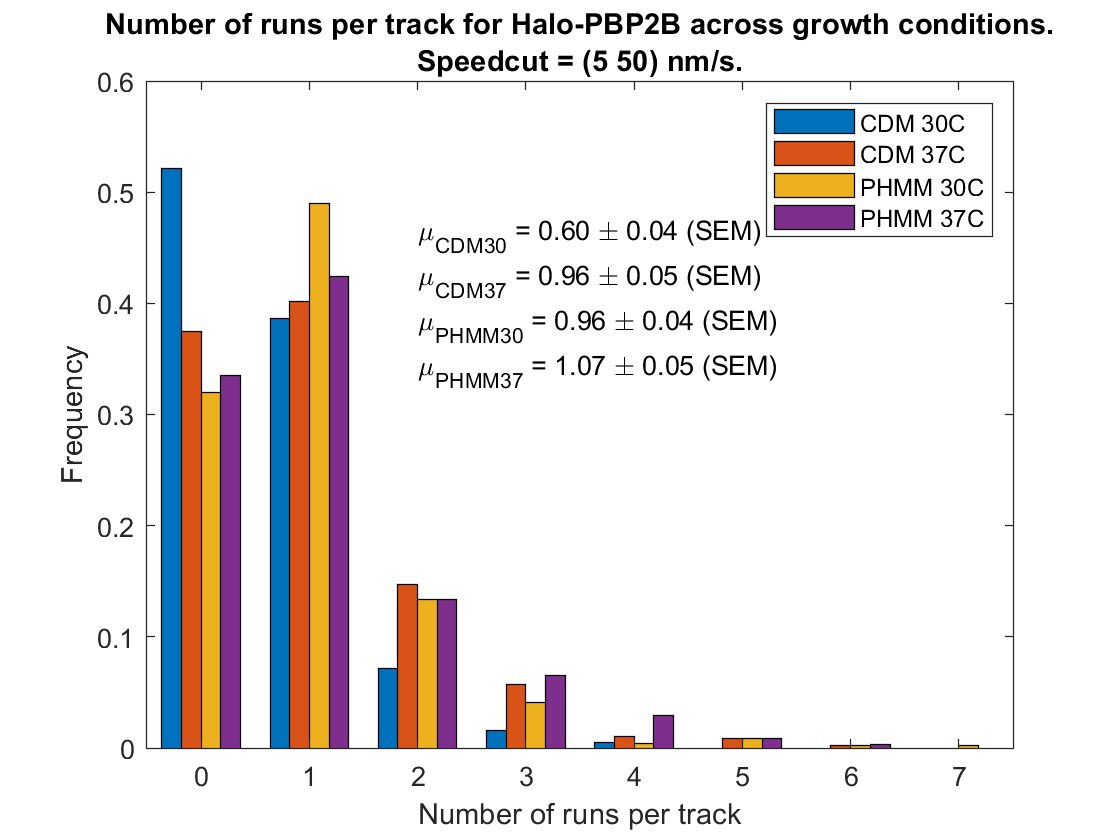

% BAR GRAPH

figure
bar(edges_n, [bin_cdm30; bin_cdm37; bin_phmm30; bin_phmm37], 1)
legend('CDM 30C', 'CDM 37C', 'PHMM 30C', 'PHMM 37C')
xlabel('Number of runs per track')
ylabel('Frequency')
text(2, 0.4, {['\mu_{CDM30} = ' num2str(cdm30_n_runs_mean,'%0.2f') ' \pm ' num2str(cdm30_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{CDM37} = ' num2str(cdm37_n_runs_mean,'%0.2f') ' \pm ' num2str(cdm37_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PHMM30} = ' num2str(phmm30_n_runs_mean,'%0.2f') ' \pm ' num2str(phmm30_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PHMM37} = ' num2str(phmm37_n_runs_mean,'%0.2f') ' \pm ' num2str(phmm37_n_runs_sem,'%0.2f') ' (SEM)']})
title({'Number of runs per track for Halo-PBP2B across growth conditions.';...
        ['Speedcut = (' num2str(speedcut(1),'%1d') ' ' num2str(speedcut(2),'%1d') ') nm/s.']})

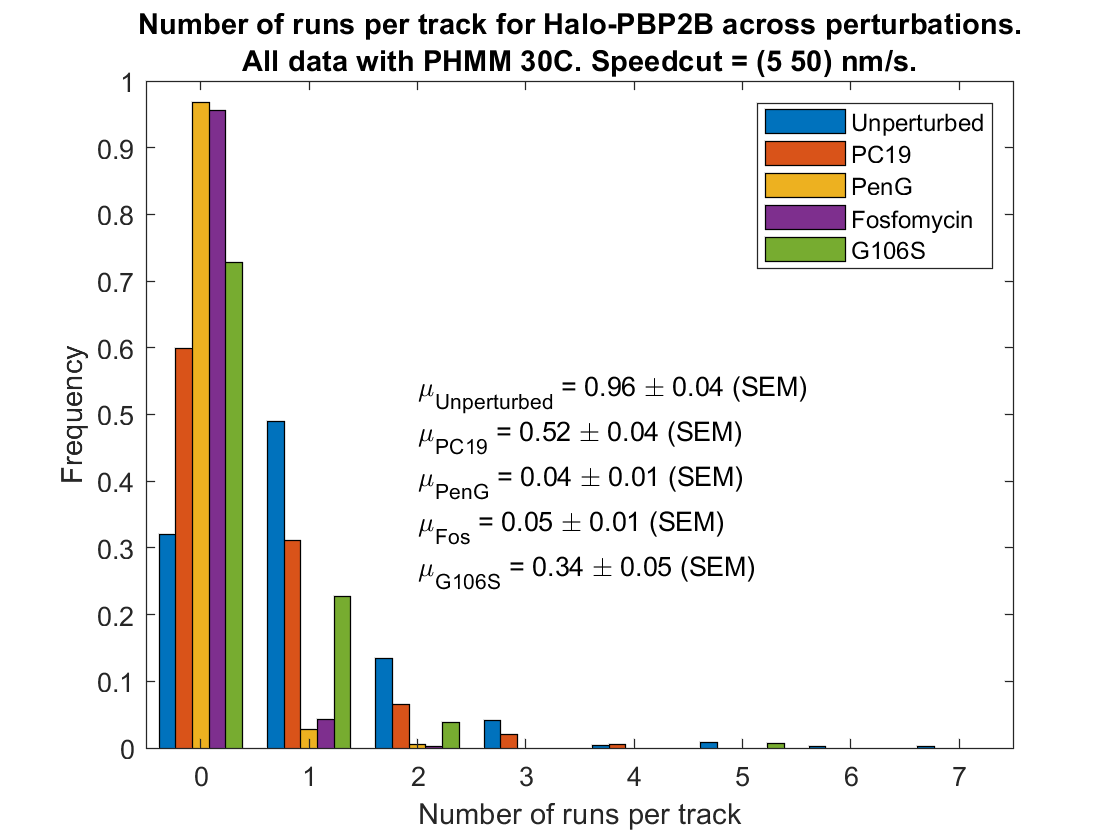

          
figure
bar(edges_n, [bin_phmm30; bin_pc19; bin_penG; bin_fos; bin_g106s], 1)
legend('Unperturbed', 'PC19', 'PenG', 'Fosfomycin', 'G106S')
xlabel('Number of runs per track')
ylabel('Frequency')
text(2, 0.4, {['\mu_{Unperturbed} = ' num2str(phmm30_n_runs_mean,'%0.2f') ' \pm ' num2str(phmm30_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PC19} = ' num2str(pc19_n_runs_mean,'%0.2f') ' \pm ' num2str(pc19_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PenG} = ' num2str(penG_n_runs_mean,'%0.2f') ' \pm ' num2str(penG_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{Fos} = ' num2str(fos_n_runs_mean,'%0.2f') ' \pm ' num2str(fos_n_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{G106S} = ' num2str(g106s_n_runs_mean,'%0.2f') ' \pm ' num2str(g106s_n_runs_sem,'%0.2f') ' (SEM)']})
title({'Number of runs per track for Halo-PBP2B across perturbations.';...
        ['All data with PHMM 30C. Speedcut = (' num2str(speedcut(1),'%1d') ' ' num2str(speedcut(2),'%1d') ') nm/s.']})

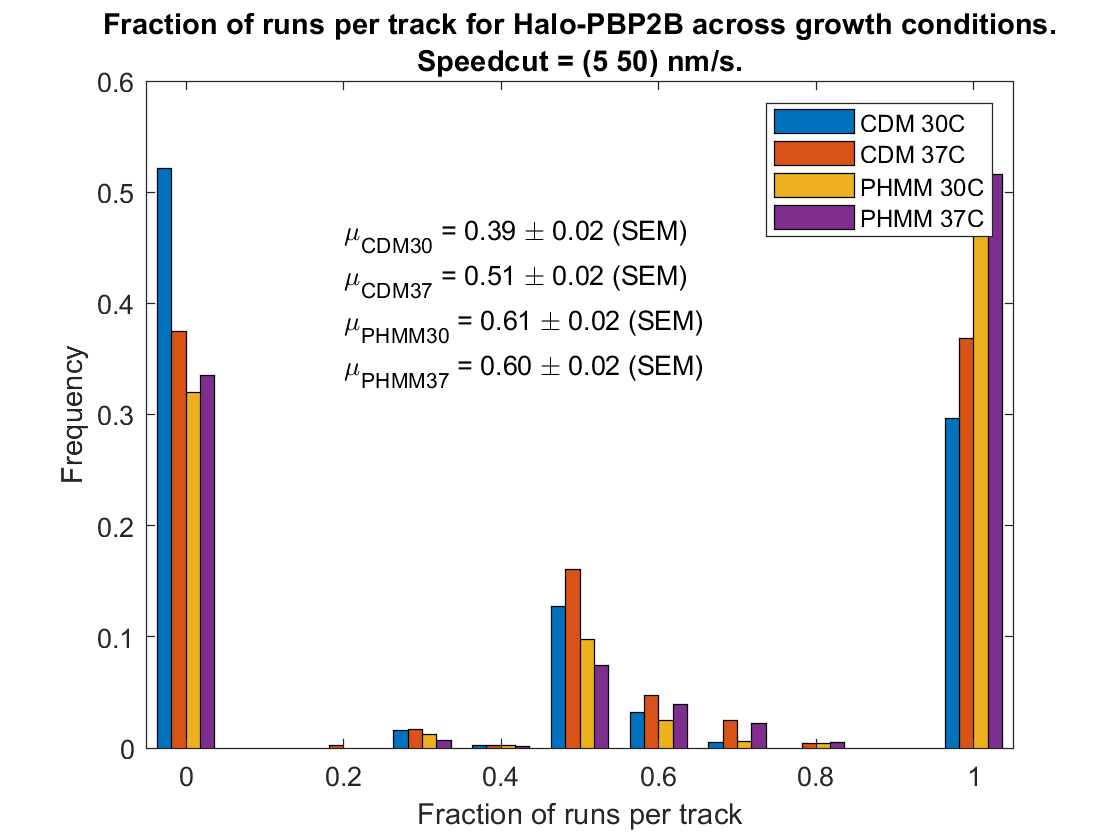

    
figure
bar(edges_f, [bin_cdm30_f; bin_cdm37_f; bin_phmm30_f; bin_phmm37_f], 1)
legend('CDM 30C', 'CDM 37C', 'PHMM 30C', 'PHMM 37C')
xlabel('Fraction of runs per track')
ylabel('Frequency')
text(0.2, 0.4, {['\mu_{CDM30} = ' num2str(cdm30_f_runs_mean,'%0.2f') ' \pm ' num2str(cdm30_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{CDM37} = ' num2str(cdm37_f_runs_mean,'%0.2f') ' \pm ' num2str(cdm37_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PHMM30} = ' num2str(phmm30_f_runs_mean,'%0.2f') ' \pm ' num2str(phmm30_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PHMM37} = ' num2str(phmm37_f_runs_mean,'%0.2f') ' \pm ' num2str(phmm37_f_runs_sem,'%0.2f') ' (SEM)']})
title({'Fraction of runs per track for Halo-PBP2B across growth conditions.';...
        ['Speedcut = (' num2str(speedcut(1),'%1d') ' ' num2str(speedcut(2),'%1d') ') nm/s.']})

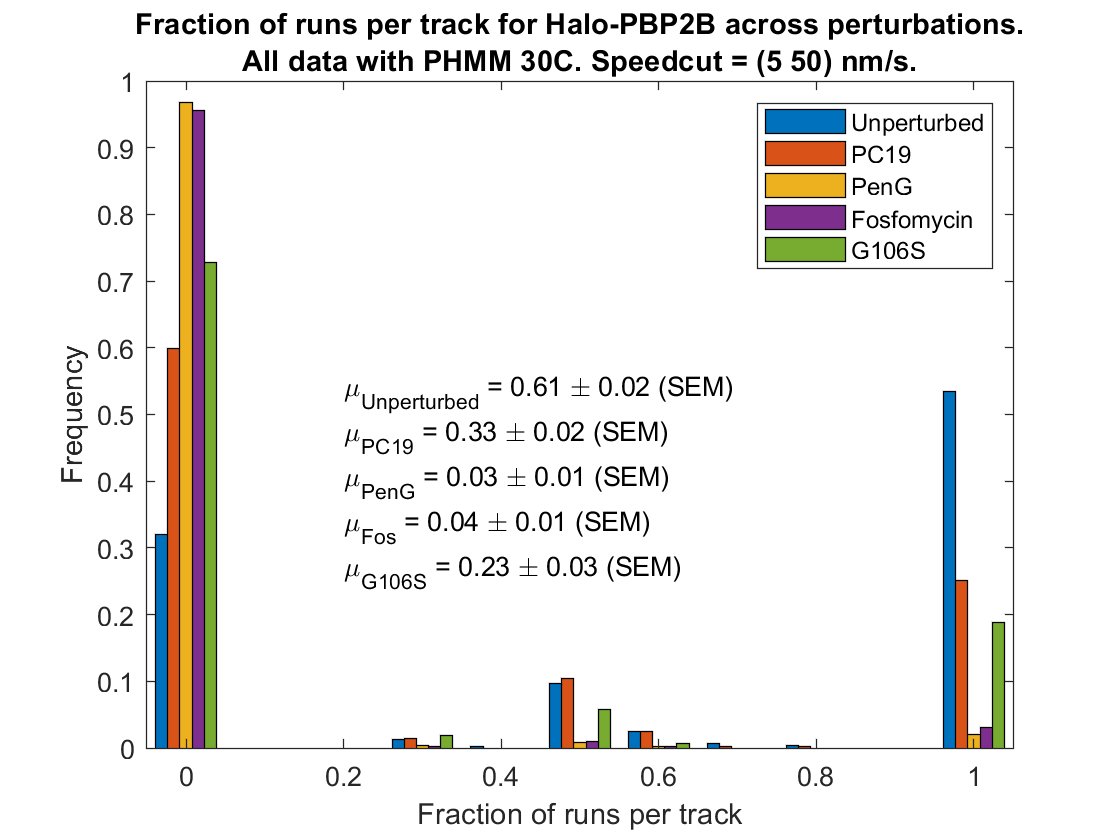

    
figure
bar(edges_f, [bin_phmm30_f; bin_pc19_f; bin_penG_f; bin_fos_f; bin_g106s_f], 1)
legend('Unperturbed', 'PC19', 'PenG', 'Fosfomycin', 'G106S')
xlabel('Fraction of runs per track')
ylabel('Frequency')
text(0.2, 0.4, {['\mu_{Unperturbed} = ' num2str(phmm30_f_runs_mean,'%0.2f') ' \pm ' num2str(phmm30_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PC19} = ' num2str(pc19_f_runs_mean,'%0.2f') ' \pm ' num2str(pc19_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{PenG} = ' num2str(penG_f_runs_mean,'%0.2f') ' \pm ' num2str(penG_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{Fos} = ' num2str(fos_f_runs_mean,'%0.2f') ' \pm ' num2str(fos_f_runs_sem,'%0.2f') ' (SEM)'],...
              ['\mu_{G106S} = ' num2str(g106s_f_runs_mean,'%0.2f') ' \pm ' num2str(g106s_f_runs_sem,'%0.2f') ' (SEM)']})
title({'Fraction of runs per track for Halo-PBP2B across perturbations.';...
        ['All data with PHMM 30C. Speedcut = (' num2str(speedcut(1),'%1d') ' ' num2str(speedcut(2),'%1d') ') nm/s.']})